## Active Shape Models

**Author:** Harshit Varma

close all;
clear variables;
clc;

% Path where results will be saved
PATH_RES = "../results/2/";

Load the data:

PATH_DATA = "../data/faces2D.mat";
data = load(PATH_DATA, "-mat");

pointsets_with_pos = data.shapes;
pointsets = pointsets_with_pos(2:3, :, :);
segments = pointsets_with_pos(1, :, :);
segments = segments(:, :, 1);
[D, N, M] = size(pointsets);

The Initial Pointsets:

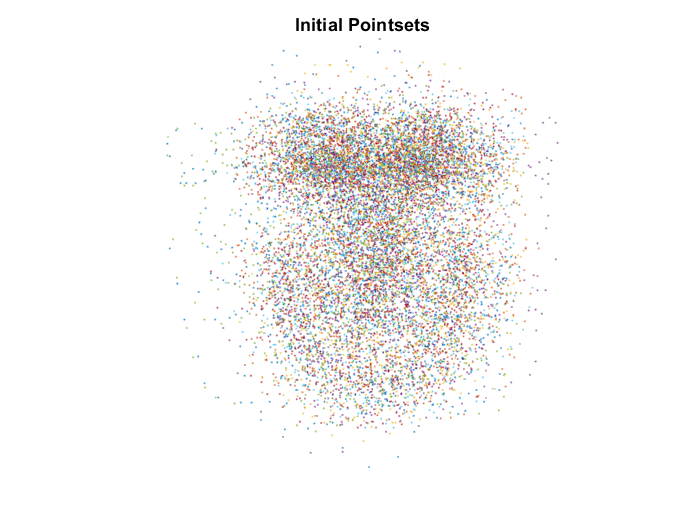

figure;
plotPointsets(pointsets, "Initial Pointsets", "without_mean", 0);
axis off;
axis equal;
saveas(gcf, PATH_RES + "initial_pointsets.jpg", "jpg");

We don't standardize the points in this approach

The initial estimate for the mean:

mu_init = updateMean(pointsets, false);

Start the optimization:

eps = 1e-8;
N_max = 20;

[mu, aligned_pointsets] = optimize2(pointsets, mu_init, eps, N_max);

Ran for 2 steps


Plot the aligned pointsets:

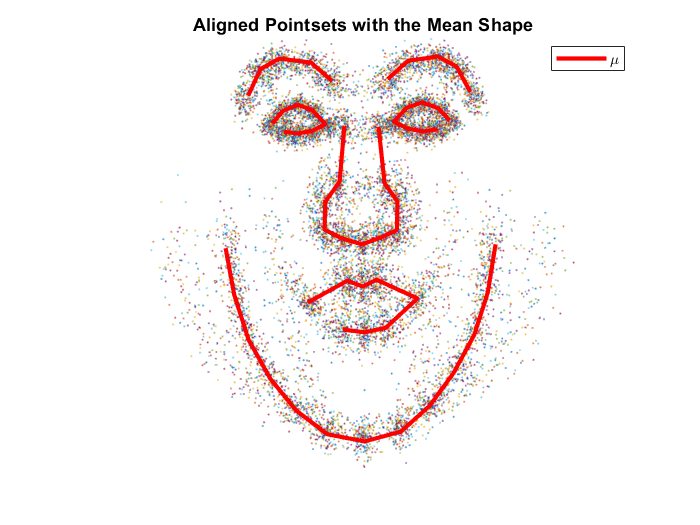

figure;
plotPointsets(aligned_pointsets, "Aligned Pointsets with the Mean Shape", "with_mean", mu, segments);
axis off;
axis equal;
saveas(gcf, PATH_RES + "aligned_pointsets.jpg", "jpg");

Create the covariance matrix:

flattened = reshape(aligned_pointsets, [D*N, M]);
C = cov(flattened'); % DN x DN

The eigenvectors and the eigenvalues:

[V, L] = eig(C);
L = diag(L);

Plot the sorted eigenvalues:

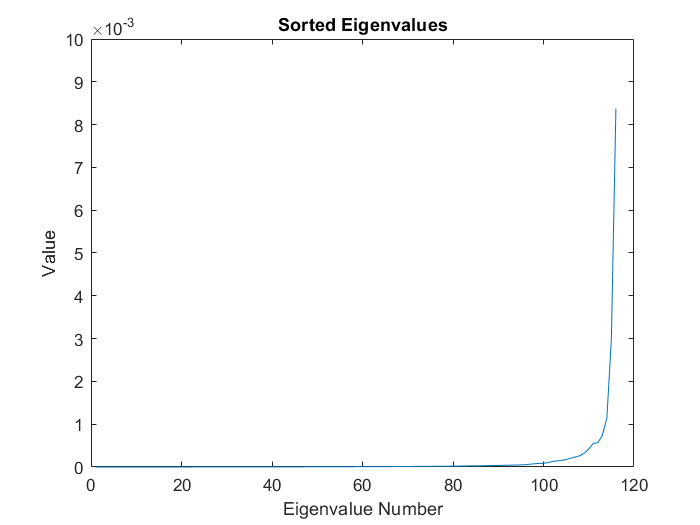

figure;
plot(L);
title("Sorted Eigenvalues");
xlabel("Eigenvalue Number");
ylabel("Value");
saveas(gcf, PATH_RES + "eigvals.jpg", "jpg");

Plot 2 sets of variations along the mean for the top 3 modes of variation:

Mode 1


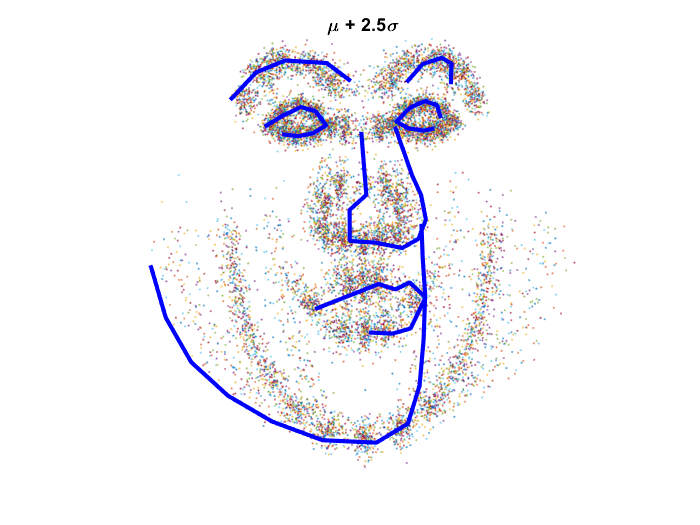

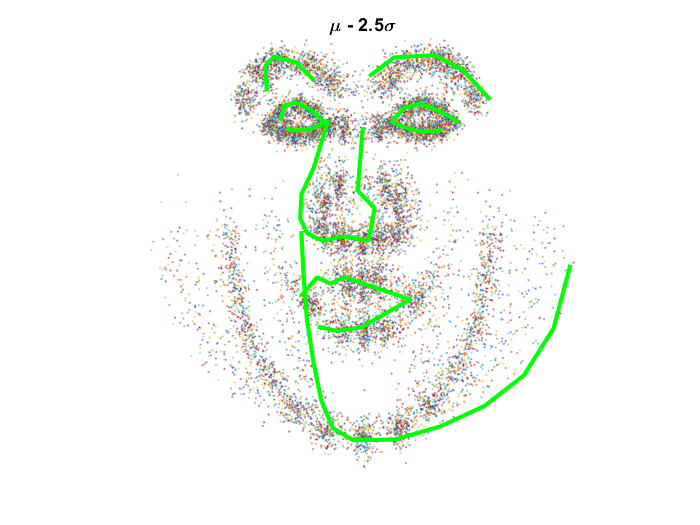

Mode 2


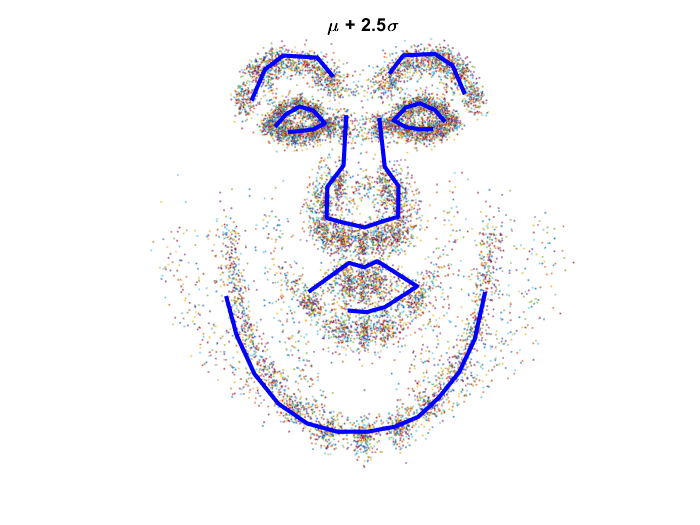

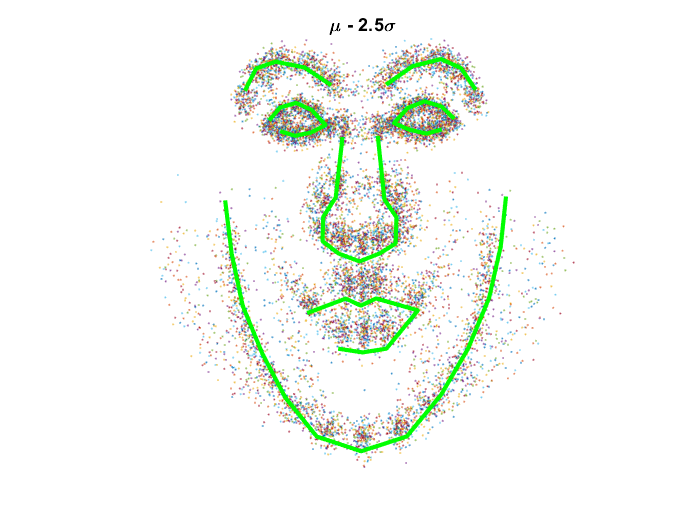

Mode 3


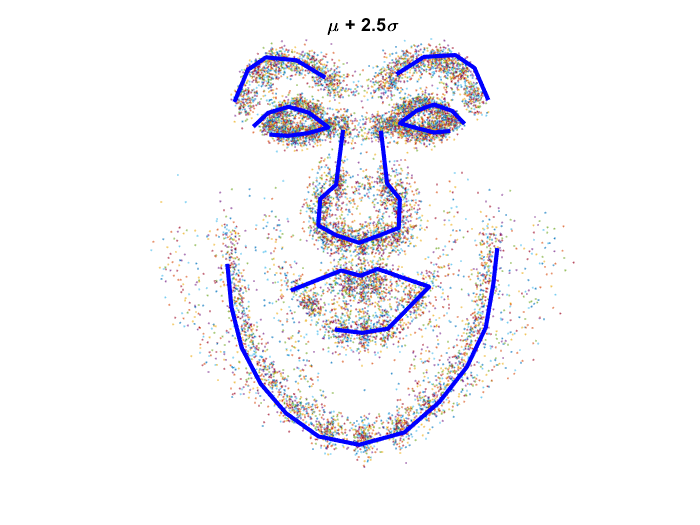

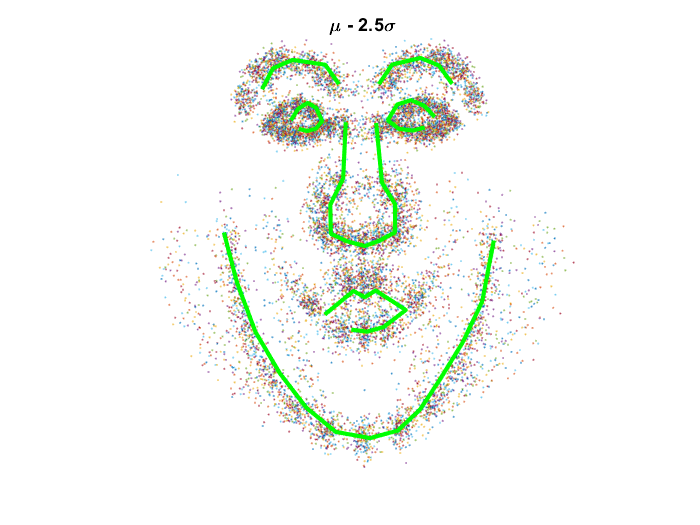

for mode = 1:3
    %figure;
    fprintf("Mode %d\n", mode);
    plotWithMode(aligned_pointsets, mu, V, L, mode, segments, PATH_RES);
end